## **Covid Detection Transfer Learning (resnet18) data augmentation**

## Load Data 

imdsTest = imageDatastore(fullfile('COVID19_CT_seg_20cases', 'test'),'IncludeSubfolders',true,'LabelSource','foldernames');
imdsTrain = imageDatastore(fullfile('UCSD_combined', 'train'),'IncludeSubfolders',true,'LabelSource','foldernames');

## Load Pretrained Network

net = resnet18;

Use `analyzeNetwork` to display an interactive visualization of the network architecture and detailed information about the network layers.

% analyzeNetwork(net);

net.Layers(1);
inputSize = net.Layers(1).InputSize;

## Replace Final Layers

Extract the layer graph from the trained network. If the network is a `SeriesNetwork` object, such as AlexNet, VGG-16, or VGG-19, then convert the list of layers in `net.Layers` to a layer graph.

if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 

Find the names of the two layers to replace. You can do this manually or you can use the supporting function [findLayersToReplace](matlab:edit(fullfile(matlabroot,'examples','nnet','main','findLayersToReplace.m'))) to find these layers automatically. 

[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer];

In most networks, the last layer with learnable weights is a fully connected layer. Replace this fully connected layer with a new fully connected layer with the number of outputs equal to the number of classes in the new data set (5, in this example). In some networks, such as SqueezeNet, the last learnable layer is a 1-by-1 convolutional layer instead. In this case, replace the convolutional layer with a new convolutional layer with the number of filters equal to the number of classes. To learn faster in the new layer than in the transferred layers, increase the learning rate factors of the layer.

numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

The classification layer specifies the output classes of the network. Replace the classification layer with a new one without class labels. `trainNetwork` automatically sets the output classes of the layer at training time. 

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

## Freeze Initial Layers

layers = lgraph.Layers;
connections = lgraph.Connections;

frozen = 1;
layers(1:frozen) = freezeWeights(layers(1:frozen));
lgraph = createLgraphUsingConnections(layers,connections);

## Train Network


 %***Image augmentation with variability***%
    % Use an augmented image datastore to automatically resize the training images. 
    % Specify additional augmentation operations to perform on the training images: 
    % randomly flip the training images along the vertical axis and randomly translate them 
    % up to 30 pixels and scale them up to 10% horizontally and vertically. 
    % Data augmentation helps prevent the network from overfitting and memorizing 
    % the exact details of the training images.  
    

    pixelRange = [-30 30];
    scaleRange = [0.9 1.1];
    rotRange = [-90 90];
    imageAugmenter = imageDataAugmenter( ...
        'RandXReflection',true, ...
        'RandXTranslation',pixelRange, ...
        'RandYTranslation',pixelRange, ...
        'RandXScale',scaleRange, ...
        'RandYScale',scaleRange, ...
        'RandRotation', rotRange);
    
    augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
        'DataAugmentation',imageAugmenter, 'ColorPreprocessing','gray2rgb');

    
% Augment data to fit new network
% augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain,"ColorPreprocessing","gray2rgb");
augimdsTest = augmentedImageDatastore(inputSize,imdsTest,"ColorPreprocessing","gray2rgb");


Specify the training options.

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'Verbose',false);

## Train the network using the training data.

all_ACCs = zeros(0);
all_Fscores = zeros(0);
% Initialize true positive, true negative, false positive, false negative.
sum_TP = 0;
sum_TN = 0;
sum_FP = 0;
sum_FN = 0;
for runs = 1:5
    net = trainNetwork(augimdsTrain,lgraph,options);

## Classify Test Images

Classify the test images using the fine-tuned network, and calculate the test accuracy.

    [YPred,probs] = classify(net,augimdsTest);
    
    % Get number of images.
    numImages = size(YPred,1);
    avg_accs = zeros([0,2]);
    % Index tracker.
    total_idx = 1;
    for i = 1:numImages/3
        % Reset sums.
        covidSum = 0;
        noncovidSum = 0;
        % Get the sum of the patient's probability of covid and noncovid
        for j = 1:3
            covidSum = covidSum + probs(total_idx,1);
            noncovidSum = noncovidSum + probs(total_idx,2);
            total_idx = total_idx + 1;
        end
        avg_accs(i,1) = round(covidSum/3,4);
        avg_accs(i,2) = round(noncovidSum/3,4);
    end
    
    for i = 1:numImages/3
        % Print patient info and results
        if(i < 10)
            fprintf('Patient %d >> Avg COVID Probability = %.4f\n',i,avg_accs(i,1));
            fprintf('\t\t\t Avg nonCOVID Probability = %.4f\n',avg_accs(i,2));
        else
                    fprintf('Patient %d >> Avg COVID Probability = %.4f\n',i,avg_accs(i,1));
            fprintf('\t\t\t  Avg nonCOVID Probability = %.4f\n',avg_accs(i,2));
        end
    end

Patient 1 >> Avg COVID Probability = 0.9633


			 Avg nonCOVID Probability = 0.0367


Patient 2 >> Avg COVID Probability = 0.9528


			 Avg nonCOVID Probability = 0.0472


Patient 3 >> Avg COVID Probability = 0.9339


			 Avg nonCOVID Probability = 0.0661


Patient 4 >> Avg COVID Probability = 0.8892


			 Avg nonCOVID Probability = 0.1108


Patient 5 >> Avg COVID Probability = 0.6075


			 Avg nonCOVID Probability = 0.3925


Patient 6 >> Avg COVID Probability = 0.6862


			 Avg nonCOVID Probability = 0.3138


Patient 7 >> Avg COVID Probability = 0.9377


			 Avg nonCOVID Probability = 0.0623


Patient 8 >> Avg COVID Probability = 0.8581


			 Avg nonCOVID Probability = 0.1419


Patient 9 >> Avg COVID Probability = 0.8846


			 Avg nonCOVID Probability = 0.1154


Patient 10 >> Avg COVID Probability = 0.9973


			  Avg nonCOVID Probability = 0.0027


Patient 11 >> Avg COVID Probability = 0.5201


			  Avg nonCOVID Probability = 0.4799


Patient 12 >> Avg COVID Probability = 0.8055


			  Avg nonCOVID Probability = 0.1945


Patient 13 >> Avg COVID Probability = 0.7559


			  Avg nonCOVID Probability = 0.2441


Patient 14 >> Avg COVID Probability = 0.4847


			  Avg nonCOVID Probability = 0.5153


Patient 15 >> Avg COVID Probability = 0.7539


			  Avg nonCOVID Probability = 0.2461


Patient 16 >> Avg COVID Probability = 0.8211


			  Avg nonCOVID Probability = 0.1789


Patient 17 >> Avg COVID Probability = 0.6715


			  Avg nonCOVID Probability = 0.3285


Patient 18 >> Avg COVID Probability = 0.8393


			  Avg nonCOVID Probability = 0.1607


Patient 19 >> Avg COVID Probability = 0.3730


			  Avg nonCOVID Probability = 0.6270


Patient 20 >> Avg COVID Probability = 0.3387


			  Avg nonCOVID Probability = 0.6613


Patient 1 >> Avg COVID Probability = 0.9998


			 Avg nonCOVID Probability = 0.0002


Patient 2 >> Avg COVID Probability = 0.9760


			 Avg nonCOVID Probability = 0.0240


Patient 3 >> Avg COVID Probability = 0.9957


			 Avg nonCOVID Probability = 0.0043


Patient 4 >> Avg COVID Probability = 0.8361


			 Avg nonCOVID Probability = 0.1639


Patient 5 >> Avg COVID Probability = 0.8729


			 Avg nonCOVID Probability = 0.1271


Patient 6 >> Avg COVID Probability = 0.8781


			 Avg nonCOVID Probability = 0.1219


Patient 7 >> Avg COVID Probability = 0.9976


			 Avg nonCOVID Probability = 0.0024


Patient 8 >> Avg COVID Probability = 0.9233


			 Avg nonCOVID Probability = 0.0767


Patient 9 >> Avg COVID Probability = 0.8470


			 Avg nonCOVID Probability = 0.1530


Patient 10 >> Avg COVID Probability = 0.9930


			  Avg nonCOVID Probability = 0.0070


Patient 11 >> Avg COVID Probability = 0.4947


			  Avg nonCOVID Probability = 0.5053


Patient 12 >> Avg COVID Probability = 0.7472


			  Avg nonCOVID Probability = 0.2528


Patient 13 >> Avg COVID Probability = 0.8022


			  Avg nonCOVID Probability = 0.1978


Patient 14 >> Avg COVID Probability = 0.0732


			  Avg nonCOVID Probability = 0.9268


Patient 15 >> Avg COVID Probability = 0.8946


			  Avg nonCOVID Probability = 0.1054


Patient 16 >> Avg COVID Probability = 0.7900


			  Avg nonCOVID Probability = 0.2100


Patient 17 >> Avg COVID Probability = 0.4992


			  Avg nonCOVID Probability = 0.5008


Patient 18 >> Avg COVID Probability = 0.8218


			  Avg nonCOVID Probability = 0.1782


Patient 19 >> Avg COVID Probability = 0.1109


			  Avg nonCOVID Probability = 0.8891


Patient 20 >> Avg COVID Probability = 0.5194


			  Avg nonCOVID Probability = 0.4806


Patient 1 >> Avg COVID Probability = 0.9961


			 Avg nonCOVID Probability = 0.0039


Patient 2 >> Avg COVID Probability = 0.9475


			 Avg nonCOVID Probability = 0.0525


Patient 3 >> Avg COVID Probability = 0.9856


			 Avg nonCOVID Probability = 0.0144


Patient 4 >> Avg COVID Probability = 0.8956


			 Avg nonCOVID Probability = 0.1044


Patient 5 >> Avg COVID Probability = 0.2715


			 Avg nonCOVID Probability = 0.7285


Patient 6 >> Avg COVID Probability = 0.7867


			 Avg nonCOVID Probability = 0.2133


Patient 7 >> Avg COVID Probability = 0.9430


			 Avg nonCOVID Probability = 0.0570


Patient 8 >> Avg COVID Probability = 0.7288


			 Avg nonCOVID Probability = 0.2712


Patient 9 >> Avg COVID Probability = 0.6083


			 Avg nonCOVID Probability = 0.3917


Patient 10 >> Avg COVID Probability = 0.9488


			  Avg nonCOVID Probability = 0.0512


Patient 11 >> Avg COVID Probability = 0.9052


			  Avg nonCOVID Probability = 0.0948


Patient 12 >> Avg COVID Probability = 0.9860


			  Avg nonCOVID Probability = 0.0140


Patient 13 >> Avg COVID Probability = 0.7884


			  Avg nonCOVID Probability = 0.2116


Patient 14 >> Avg COVID Probability = 0.6956


			  Avg nonCOVID Probability = 0.3044


Patient 15 >> Avg COVID Probability = 0.9119


			  Avg nonCOVID Probability = 0.0881


Patient 16 >> Avg COVID Probability = 0.8109


			  Avg nonCOVID Probability = 0.1891


Patient 17 >> Avg COVID Probability = 0.8632


			  Avg nonCOVID Probability = 0.1368


Patient 18 >> Avg COVID Probability = 0.7121


			  Avg nonCOVID Probability = 0.2879


Patient 19 >> Avg COVID Probability = 0.8360


			  Avg nonCOVID Probability = 0.1640


Patient 20 >> Avg COVID Probability = 0.3846


			  Avg nonCOVID Probability = 0.6154


Patient 1 >> Avg COVID Probability = 0.3902


			 Avg nonCOVID Probability = 0.6098


Patient 2 >> Avg COVID Probability = 0.4026


			 Avg nonCOVID Probability = 0.5974


Patient 3 >> Avg COVID Probability = 0.8104


			 Avg nonCOVID Probability = 0.1896


Patient 4 >> Avg COVID Probability = 0.2653


			 Avg nonCOVID Probability = 0.7347


Patient 5 >> Avg COVID Probability = 0.0175


			 Avg nonCOVID Probability = 0.9825


Patient 6 >> Avg COVID Probability = 0.6327


			 Avg nonCOVID Probability = 0.3673


Patient 7 >> Avg COVID Probability = 0.1033


			 Avg nonCOVID Probability = 0.8967


Patient 8 >> Avg COVID Probability = 0.0454


			 Avg nonCOVID Probability = 0.9546


Patient 9 >> Avg COVID Probability = 0.0576


			 Avg nonCOVID Probability = 0.9424


Patient 10 >> Avg COVID Probability = 0.9844


			  Avg nonCOVID Probability = 0.0156


Patient 11 >> Avg COVID Probability = 0.0715


			  Avg nonCOVID Probability = 0.9285


Patient 12 >> Avg COVID Probability = 0.1483


			  Avg nonCOVID Probability = 0.8517


Patient 13 >> Avg COVID Probability = 0.4351


			  Avg nonCOVID Probability = 0.5649


Patient 14 >> Avg COVID Probability = 0.0235


			  Avg nonCOVID Probability = 0.9765


Patient 15 >> Avg COVID Probability = 0.2725


			  Avg nonCOVID Probability = 0.7275


Patient 16 >> Avg COVID Probability = 0.1401


			  Avg nonCOVID Probability = 0.8599


Patient 17 >> Avg COVID Probability = 0.4316


			  Avg nonCOVID Probability = 0.5684


Patient 18 >> Avg COVID Probability = 0.3626


			  Avg nonCOVID Probability = 0.6374


Patient 19 >> Avg COVID Probability = 0.0286


			  Avg nonCOVID Probability = 0.9714


Patient 20 >> Avg COVID Probability = 0.0261


			  Avg nonCOVID Probability = 0.9739


Patient 1 >> Avg COVID Probability = 1.0000


			 Avg nonCOVID Probability = 0.0000


Patient 2 >> Avg COVID Probability = 1.0000


			 Avg nonCOVID Probability = 0.0000


Patient 3 >> Avg COVID Probability = 0.9999


			 Avg nonCOVID Probability = 0.0001


Patient 4 >> Avg COVID Probability = 0.9994


			 Avg nonCOVID Probability = 0.0006


Patient 5 >> Avg COVID Probability = 0.9976


			 Avg nonCOVID Probability = 0.0024


Patient 6 >> Avg COVID Probability = 0.9999


			 Avg nonCOVID Probability = 0.0001


Patient 7 >> Avg COVID Probability = 0.9997


			 Avg nonCOVID Probability = 0.0003


Patient 8 >> Avg COVID Probability = 0.9993


			 Avg nonCOVID Probability = 0.0007


Patient 9 >> Avg COVID Probability = 0.9988


			 Avg nonCOVID Probability = 0.0012


Patient 10 >> Avg COVID Probability = 1.0000


			  Avg nonCOVID Probability = 0.0000


Patient 11 >> Avg COVID Probability = 0.9829


			  Avg nonCOVID Probability = 0.0171


Patient 12 >> Avg COVID Probability = 0.9787


			  Avg nonCOVID Probability = 0.0213


Patient 13 >> Avg COVID Probability = 0.9996


			  Avg nonCOVID Probability = 0.0004


Patient 14 >> Avg COVID Probability = 0.9736


			  Avg nonCOVID Probability = 0.0264


Patient 15 >> Avg COVID Probability = 0.9990


			  Avg nonCOVID Probability = 0.0010


Patient 16 >> Avg COVID Probability = 0.9608


			  Avg nonCOVID Probability = 0.0392


Patient 17 >> Avg COVID Probability = 0.9992


			  Avg nonCOVID Probability = 0.0008


Patient 18 >> Avg COVID Probability = 0.9986


			  Avg nonCOVID Probability = 0.0014


Patient 19 >> Avg COVID Probability = 0.7901


			  Avg nonCOVID Probability = 0.2099


Patient 20 >> Avg COVID Probability = 0.8766


			  Avg nonCOVID Probability = 0.1234


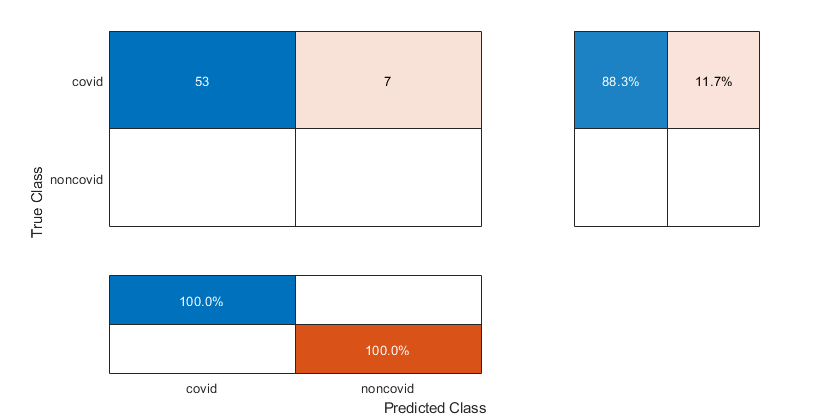

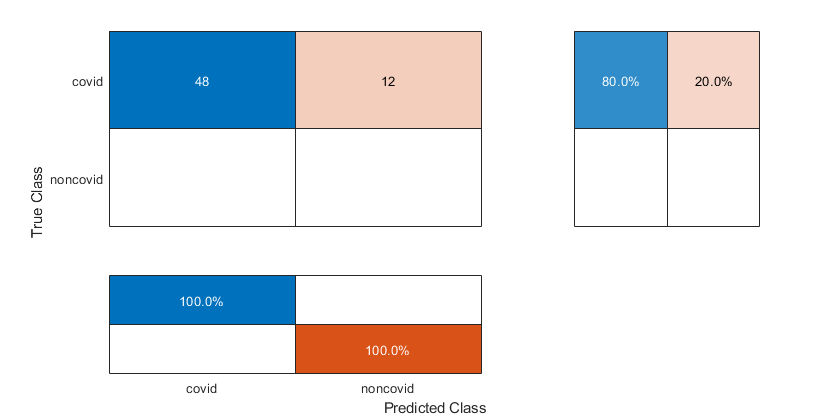

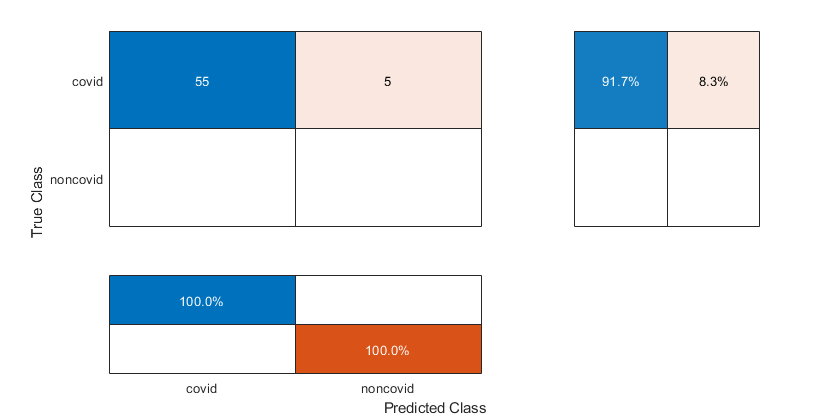

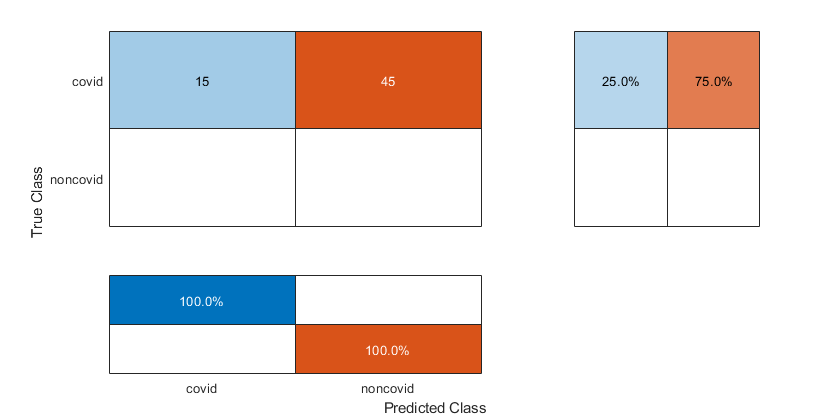

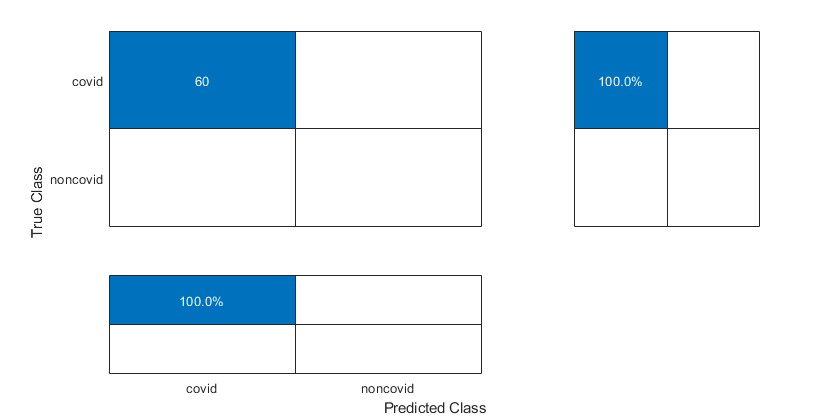

    
    % Extract the class labels from the test data.
    YTest = imdsTest.Labels;
    
    accuracy = mean(YPred == YTest);
    
    % Calculate Average F-score.
    s = max(size(unique(YTest)));
    conf_values = confusionmat(YTest, YPred);
    tp_m = diag(conf_values); 
    for i = 1:s
       % Get true positive, false negative, false positive
        sum_TP = sum_TP + conf_values(1,1);
        TP = conf_values(1,1);
        sum_FN = sum_FN + conf_values(1,2);
        FN = conf_values(1,2);
        sum_FP = sum_FP + conf_values(2,1);
        FP = conf_values(2,1);
        sum_TN = sum_TN + conf_values(2,2);
        TN = conf_values(2,2);
        
        % Calculate Recall, precision, fscore
        Recall = TP /(TP + FN);
        if isnan(Recall)
            Recall = 0;
        end
        % Calculate Precision
        Precision = TP / (TP + FP);
        if isnan(Precision)
            Precision = 0;
        end
        % Calculate FScore
        FScore = (2*(Precision * Recall)) / (Precision+Recall);
        if isnan(FScore)
            FScore = 0;
        end
    end
    
    % Display confusion chart.
    fig = figure;
    conf = confusionchart(YTest, YPred,'RowSummary','row-normalized','ColumnSummary','column-normalized');

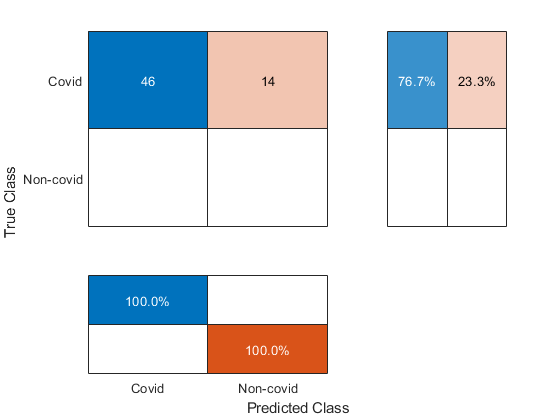

    fig_Position = fig.Position;
    fig_Position(3) = fig_Position(3)*1.5;
    fig.Position = fig_Position;
    
    all_ACCs = [all_ACCs accuracy];
    all_Fscores = [all_Fscores FScore];

end

% Get the average of all of the labels.
sum_TP = round(sum_TP/5);
sum_TN = round(sum_TN/5);
sum_FP = round(sum_FP/5);
sum_FN = round(sum_FN/5);
% Combined CM
combined_mat = [sum_TP,  sum_FN; sum_FP, sum_TN];

% Display combined confusion chart.
figure;
conf = confusionchart(combined_mat,["Covid", "Non-covid"],'RowSummary','row-normalized','ColumnSummary','column-normalized');

avg_ACC = mean(all_ACCs)
avg_FScore = mean(all_Fscores)

stdDev_ACC = std(all_ACCs)
stdDev_Fscore = std(all_Fscores)

Display four sample validation images with predicted labels and the predicted probabilities of the images having those labels. With Actiavation Heatmaps

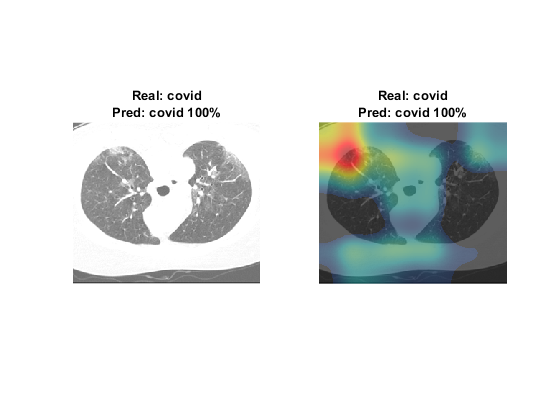

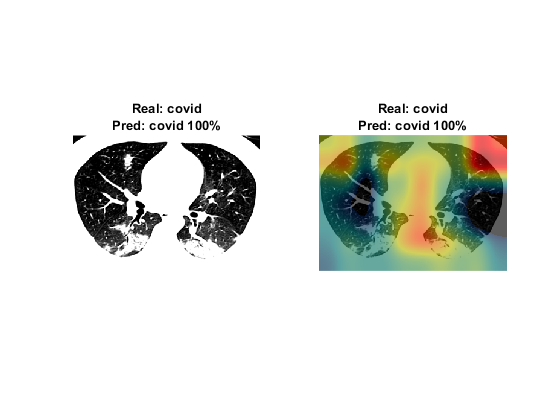

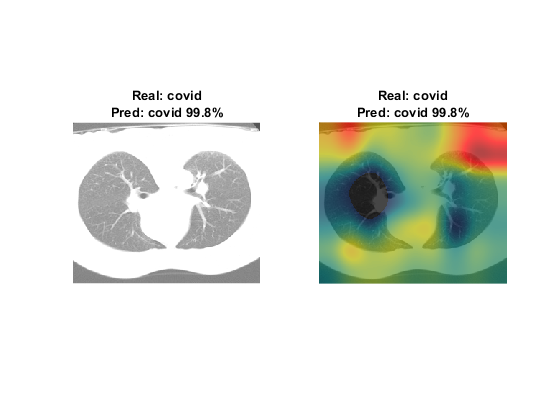

idx = randperm(numel(imdsTest.Files),3);
figure
for i = 1:3 
    I = readimage(imdsTest,idx(i));
    actlabel = YTest(idx(i));
    predlabel = YPred(idx(i));
    
    layerName = 'res5b_relu';
    
    %Compute the activations of the resized image
    % in the ReLU layer that follows the last convolutional layer of the network
    imResized = imresize(I,[inputSize(1), NaN]);
    imageActivations = activations(net,imResized,layerName);
    
    %global average pooling (get average of activations)
    scores = squeeze(mean(imageActivations,[1 2]));
    fcWeights = net.Layers(end-2).Weights;
    fcBias = net.Layers(end-2).Bias;
    
    %get predicted class/classes with highes scores for CAM
    scores =  fcWeights*scores + fcBias;
    [~,classIds] = maxk(scores,2);
    weightVector = shiftdim(fcWeights(classIds(1),:),-1);
    classActivationMap = sum(imageActivations.*weightVector,3);
    
    %get the top class labels and the final normalized class scores
    scores = exp(scores)/sum(exp(scores));     
    maxScores = scores(classIds);
    labels = class(classIds);
    
    %Plot the class activation map
    figure;
    subplot(1,2,1)
    imshow(imResized)
    title({"Real: " + string(actlabel), "Pred: " + string(predlabel) + " " + ...
    num2str(100*max(probs(idx(i),:)),3) + "%"});
    
    subplot(1,2,2)
    CAMshow(imResized,classActivationMap)
    title({"Real: " + string(actlabel), "Pred: " + string(predlabel) + " " + ...
    num2str(100*max(probs(idx(i),:)),3) + "%"});

end


drawnow




HELPER FUNCTIONS FOR CAM

function CAMshow(im,CAM)
    imSize = size(im);
    CAM = imresize(CAM,imSize(1:2));
    CAM = normalizeImage(CAM);
    CAM(CAM<0.2) = 0;
    cmap = jet(255).*linspace(0,1,255)';
    CAM = ind2rgb(uint8(CAM*255),cmap)*255;
    
    combinedImage = double(rgb2gray(im))/2 + CAM;
    combinedImage = normalizeImage(combinedImage)*255;
    imshow(uint8(combinedImage));
end


function N = normalizeImage(I)
    minimum = min(I(:));
    maximum = max(I(:));
    N = (I-minimum)/(maximum-minimum);
end